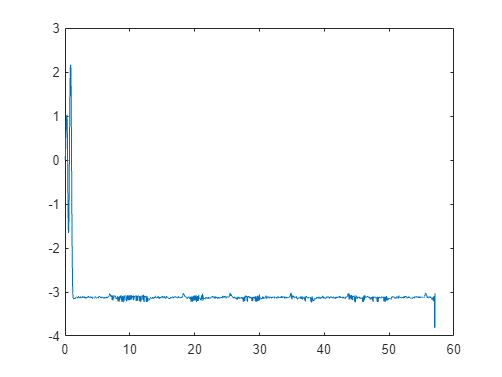

clc; clear; close all;
load("rmsTest.mat")

timeCut = 1;
rmsTest.one.baseAngle(1:timeCut) =[];
rmsTest.one.time(1:timeCut) =[];
rmsTest.one.time = rmsTest.one.time - rmsTest.one.time(1);

rmsTest.one.pendAngleZeroDwn(1:timeCut) =[];
rmsTest.one.pendAngleZeroUp(1:timeCut) =[];
rmsTest.one.timeTrigger(1:timeCut) =[];
rmsTest.one.Current(1:timeCut) =[];
rmsTest.one.Current = rmsTest.one.Current;

plot(rmsTest.one.time, rmsTest.one.pendAngleZeroDwn)

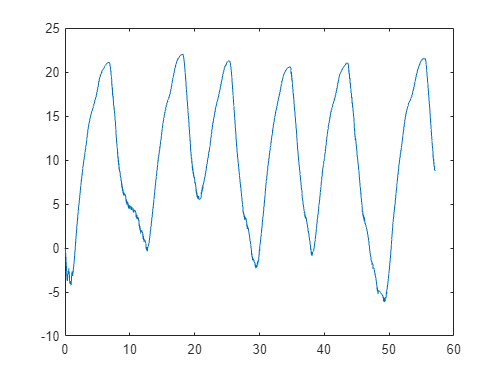

plot(rmsTest.one.time, rmsTest.one.baseAngle)

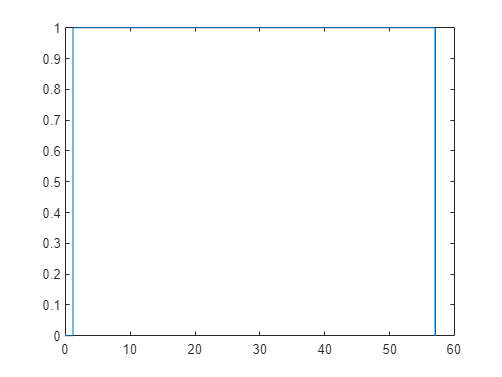

plot(rmsTest.one.time, rmsTest.one.timeTrigger)

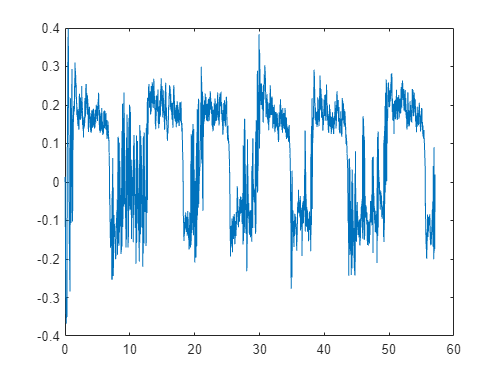

plot(rmsTest.one.time, rmsTest.one.Current)

dd

triggerTime = 235*0.005 % s

triggerTime = 1.1750

triggerIndex = 235

triggerIndex = 235

Plotting paramters 

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

Plotting for the report pendulum swing-up

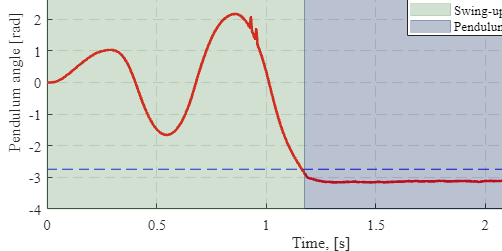

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 500;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.pendAngleZeroDwn(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

plt2 = plot([0, lengthOfPltTime], [pi-0.4, pi-0.4]);
plt2.Color = 'b';
plt2.LineStyle = '--';

plt3 = plot([0, lengthOfPltTime], [-pi+0.4, -pi+0.4]);
plt3.Color = 'b';
plt3.LineStyle = '--';

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:0.5:10];                    % Divisions on axes
ax.YTick = [-5:1:5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [-4, 4];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)


%yl = [-4, 4];
patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)


leg = legend('Pendulum angle', 'Switching thresholds','', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "northeast";

hold off
grid on
box on

Plotting fo the repport. Base under swing up

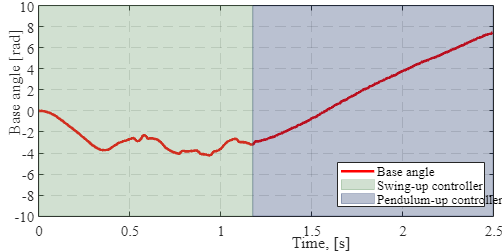

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
%lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.baseAngle(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
%ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-10:2:10];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Base angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [ax.YTick(1), ax.YTick(end)];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Base angle', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";

hold off
grid on
box on

Plotting fo the repport. Current under swing up

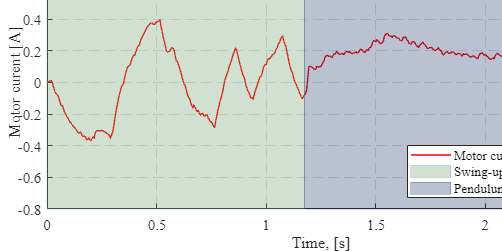

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
%lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.Current(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
%ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-0.8:0.2:0.8];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend
label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Motor curent [A]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [ax.YTick(1), ax.YTick(end)];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)


%yl = [-4, 4];
patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)



leg = legend('Motor current', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";

hold off
grid on
box on

Plotting for the report. Pendulum Up controller pendulum

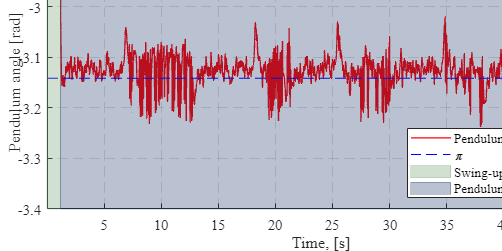

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 10786;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.pendAngleZeroDwn(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

plt2 = plot([0, lengthOfPltTime], [-pi, -pi]);
plt2.Color = 'b';
plt2.LineStyle = '--';

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-3.4:0.1:-2.9];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Pendulum angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [ax.YTick(1), ax.YTick(end)];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Pendulum angle','\pi' , 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Plotting for the report. Pendulum Up controller base

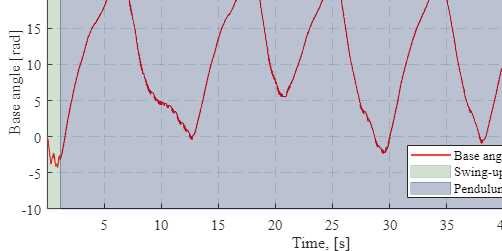

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 10786;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.baseAngle(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-10:5:25];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Base angle [rad]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [ax.YTick(1), ax.YTick(end)];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Base angle', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Plotting for the report. Pendulum Up controller base

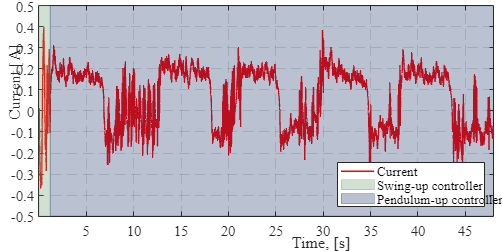

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 10786;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:end), rmsTest.one.Current(1:end));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW1;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [5:5:55];                    % Divisions on axes
ax.YTick = [-0.5:0.1:0.5];                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Current [A]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


yl = [ax.YTick(1), ax.YTick(end)];
patch([0 0 triggerTime triggerTime],[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.4 .6 .4],'edgecolor',[.4 .6 .4],...
    'facealpha',0.3,'edgealpha',0.3)

patch([triggerTime triggerTime lengthOfPltTime lengthOfPltTime] ,[yl(1) yl(2) yl(2) yl(1)],'k',...
    'facecolor',[.1 .2 .4],'edgecolor',[.1 .2 .4],...
    'facealpha',0.3,'edgealpha',0.3)

leg = legend('Current', 'Swing-up controller', 'Pendulum-up controller');
leg.Location = "southeast";
xlim([0 48])
ylim(yl)

hold off
grid on
box on

Calculate RMS

tStartIndex = triggerIndex; % when t=triggerTime
tStopIndex = tStartIndex + 40*200; % When t=4triggerTime


pendRMS = rms(rmsTest.one.pendAngleZeroDwn(tStartIndex:tStopIndex)+pi)

pendRMS = 0.0309

baseRMS = rms(rmsTest.one.baseAngle(tStartIndex:tStopIndex))

baseRMS = 12.8853

currentRMS = rms(rmsTest.one.Current(tStartIndex:tStopIndex))

currentRMS = 0.1542